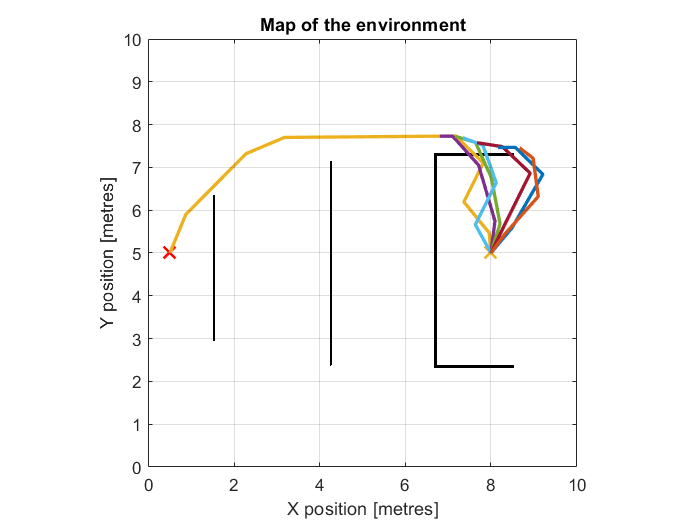

clf;
clear
clc;
load("Astar_scenario6_dynamic.mat");
show(plotObstacleMap); grid on; hold on;
xlabel('X position [metres]');
ylabel('Y position [metres]');
title('Map of the environment');
%
pathName = {'Initial Path'};%;'First re-plan';'Second re-plan';...
      % 'Third re-plan'};
%
goalPlot(2) = plot(goal(2),goal(1),'Marker','x','MarkerEdgeColor','[0.9290, 0.6940, 0.1250]',...
 'LineWidth',1.5,'MarkerSize',10,'DisplayName','Goal');
goalPlot(1) = plot(xio(1,20)+5,xio(1,19)+5,'Marker','x','MarkerEdgeColor','red',...
 'LineWidth',1.5,'MarkerSize',10,'DisplayName','Start');
set(goalPlot(1:2),'linestyle','none');
for i=1:length(pathStorage)
x = pathStorage(i).Path(:,1);
y = pathStorage(i).Path(:,2);
plotnr(i) = plot(x,y,'LineWidth',2);%,'DisplayName',pathName{i});
end


%trajectory(1) = plot(xio(:,20)+5,xio(:,19)+5,'blue','LineStyle',...
%    '--','LineWidth',2,'DisplayName','Path');


%legend;